# [**k-Nearest Neighbors Classifier**](https://apmonitor.com/pds/index.php/Main/KNearestNeighbors)

## Introduction 

Neighbors based classification is a type of lazy learning as it does not attempt to construct a general internal model, but simply stores instances of the training data. Classification is computed from a simple majority vote of the k nearest neighbors of each point. Specifically, k-Nearest Neighbors (kNN) is a type of instance-based learning or non-parametric learning algorithm, where the model is not explicitly trained, but instead makes predictions by comparing new data points to the nearest neighbors in the training data. The algorithm works by calculating the distances between the new data point and the training data, selecting the k-nearest data points, and then making a prediction based on the class or label of the selected neighbors.

**Advantages:** This algorithm is simple to implement, robust to noisy training data, and effective if training data is large.

**Disadvantages:** Need to determine the value of *k* and the computation cost is high as it needs to computer the distance of each instance to all the training samples. A feedback loop can be added to determine the number of neighbors.

**k-Nearest Neighbors in Matlab**

Here is an example of k-nearest neighbors in Matlab using the following, based upon test data :

% Load the data
load fisheriris
X_fish = meas(:,3:4);
Y_fish = species;

% Split the data into training and testing sets
idx = randperm(size(X_fish,1));
X_train = X_fish(idx(1:100),:);
Y_train = Y_fish(idx(1:100));
X_test = X_fish(idx(101:end),:);
Y_test = Y_fish(idx(101:end));

% Create a k-nearest neighbors classifier with 3 neighbors
model = fitcknn(X_train, Y_train, NumNeighbors=3);

% Make predictions on the test set
y_pred = predict(model, X_test);

In this example, we first create a k-nearest neighbors classifier with 3 neighbors using the fitcknn function. Finally, we use the trained model to make predictions on the test set using the *predict* method. The number of neighbors is the hyperparameter for tuning the performance. Change *n_neighbors* to a higher number to gain more consensus for the classification.

% Create a k-nearest neighbors classifier with 5 neighbors
model = fitcknn(X_train, Y_train, NumNeighbors=5);

% Make predictions on the test set
y_pred_5 = predict(model, X_test);

## **Optical Character Recognition with k-Nearest Neighbors**

Optical character recognition (OCR) is the process of extracting text from images or scanned documents. OCR algorithms are typically based on machine learning models that are trained on large datasets of images containing text.

Here is an example of OCR using a k-nearest neighbors (kNN) classifier:

%%Load in the ex4data for usage
load('ex4data1.mat');

%%Split data 75-25
cv = cvpartition(size(X,1),'HoldOut',0.25);
idx = cv.test;

% Separate to training and test data
X_train_ocr = X(~idx,:);
Y_train_ocr = y(~idx,:);
X_test_ocr = X(idx,:);
Y_test_ocr = y(idx,:);


% Create a k-nearest neighbors classifier with 3 neighbors
model = fitcknn(X_train_ocr, Y_train_ocr, NumNeighbors=3);

% Make predictions on the test set
y_pred = predict(model, X_test_ocr);

% Compare Predictions to actual values 

predictions = y_pred == Y_test_ocr;

%Divide predictions by number of total predicitions
accuracy = sum(predictions)/numel(Y_test_ocr)

accuracy = 0.9328

In this example, we first load the digits dataset from ex4data1.mat, which contains images of handwritten digits. Then, we create a k-nearest neighbors classifier with 3 neighbors using the KNeighborsClassifier class. Next, we train the model on the the train dataset we developed. Finally, we use the trained model to make predictions on new images, and calculate accuracy by comparing the predicted values to the actual values, summing the accurate values and dividing this by total number of observations.

## 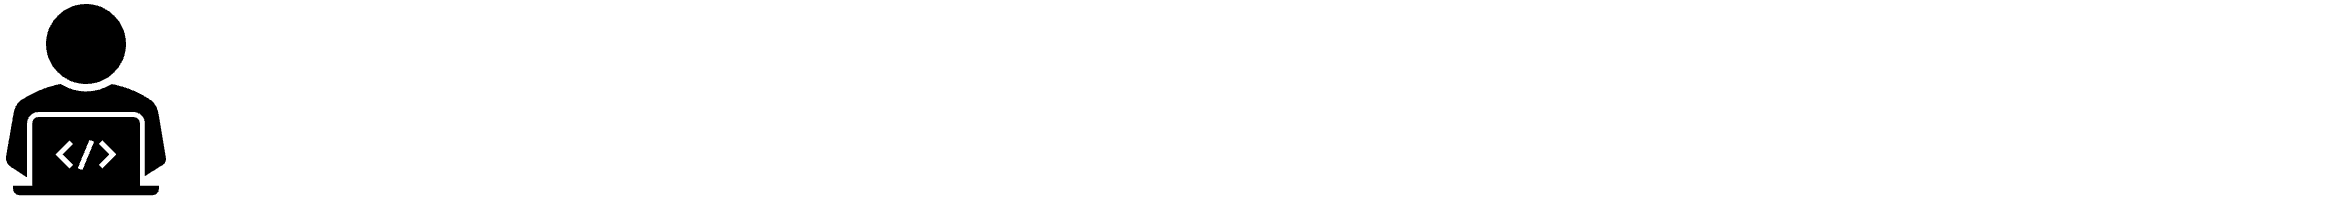

## **k-Nearest Neighbors for Animal Classification**

It is proposed to classify cats and dogs by weight. A total of 16 animals are measured and the data is split into a test (3) and train (13) set.

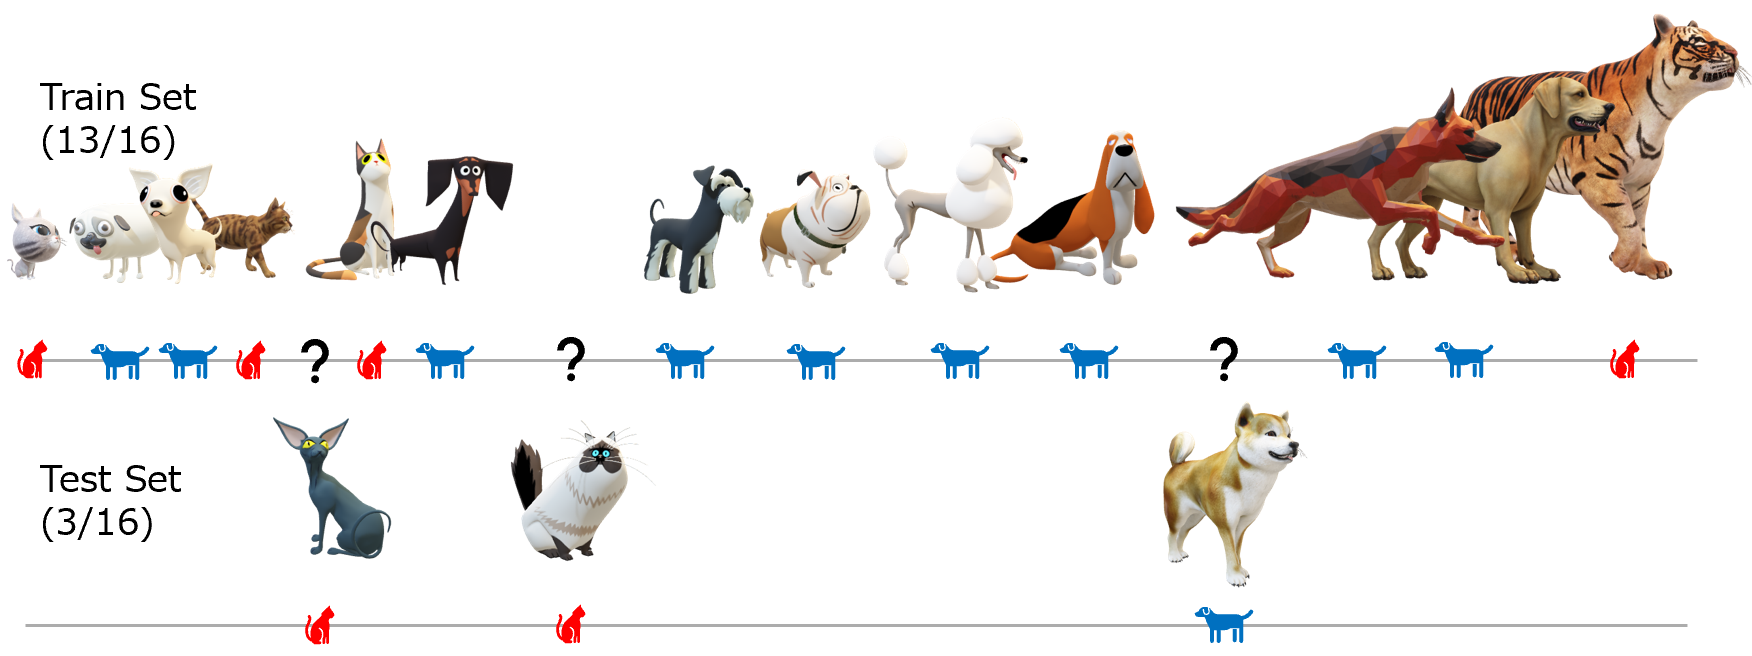

The accuracy of the classifier is defined as the number of correct test classifications divided by the total number in the test set.

Accuracy=(Correct / Total) * 100%

What is the accuracy of the dog and cat classifier with *k=2*?

Accuracy = 2/3 * 100

Accuracy = 66.6667

## k-Nearest Neighbors Programmming

Using only MATLAB code (not fitcknn() function), create a k-Nearest Neighbors classifier. Compare results with actual values and calculate accuracy to evaluate the performance of the code.

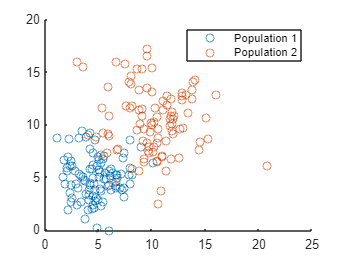

% Define parameters for population 1
mean_1 = 5;
std_1 = 2;

% Generate data for population 1, including labels
pop_1 = mean_1 + std_1 * randn(100, 2);
pop_1_label = ones(100,1);
pop1 = cat(2,pop_1,pop_1_label);


% Define parameters for population 2
mean_2 = 10;
std_2 = 3;

% Generate data for population 2, including labels
pop_2 = mean_2 + std_2 * randn(100, 2);
pop_2_label = 2*ones(100,1);
pop2 = cat(2,pop_2,pop_2_label);

% Plot the data
figure;
scatter(pop_1(:,1),pop_1(:,2));
hold on;
scatter(pop_2(:,1),pop_2(:,2));
legend('Population 1', 'Population 2');

Join the two population datasets, then separate into train and test sets.

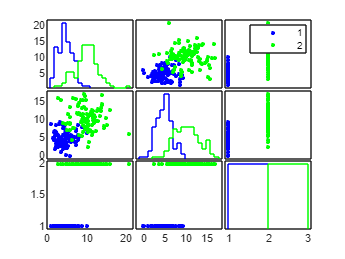

pop = cat(1,pop1,pop2);

%%Split data 75-25
cv_pop = cvpartition(200,'HoldOut',0.25);
idx_pop = test(cv_pop);
gplotmatrix(pop,[],pop(:,3))


% Separate to training and test data
train_pop = pop(~idx_pop,:);
test_pop = pop(idx_pop,:);

%%Define what number of neighbors you want 
n = 3;

%%%Add fourth column to train_pop to store predicted groupings
predCol = zeros(length(test_pop),1)

predCol =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


test_pop = cat(2,test_pop,predCol)

test_pop =     6.0905    5.1005    1.0000         0
    1.1534    8.6935    1.0000         0
    5.9801    4.1744    1.0000         0
    6.8143    5.1821    1.0000         0
    5.1207    5.0223    1.0000         0
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0



for i = 1:length(test_pop)
    t = test_pop(i,:);
    d = [];
    for j = 1:length(train_pop)
        
        x2 = t(1) - train_pop(j,1);
        y2 = t(2) - train_pop(j,2);
        d(j,:) = [sqrt(x2^2 + y2^2),train_pop(j,3)];
    end 
    %% Sort the column by distance
    d = sortrows(d,1);
    d = d(1:n,:);
    m = mode(d(:,2));
    test_pop(i,4) = m;
end 

d =     0.4198    1.0000
    0.5301    1.0000
    0.5602    1.0000
    0.6257    1.0000
    0.7011    1.0000
    0.7604    1.0000
    0.8470    1.0000
    0.8514    1.0000
    0.9924    1.0000
    1.0874    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000         0
    5.9801    4.1744    1.0000         0
    6.8143    5.1821    1.0000         0
    5.1207    5.0223    1.0000         0
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     1.1817    1.0000
    2.0366    1.0000
    2.0551    1.0000
    2.2011    1.0000
    2.4234    1.0000
    2.5325    1.0000
    2.8815    1.0000
    2.9592    2.0000
    2.9970    1.0000
    3.0043    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000         0
    6.8143    5.1821    1.0000         0
    5.1207    5.0223    1.0000         0
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.0825    1.0000
    0.4817    1.0000
    0.6822    1.0000
    0.7149    1.0000
    0.7613    1.0000
    0.7678    1.0000
    0.8139    1.0000
    0.8289    1.0000
    0.8585    1.0000
    1.1056    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000         0
    5.1207    5.0223    1.0000         0
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.1074    1.0000
    0.2832    1.0000
    0.3633    1.0000
    0.6629    1.0000
    0.8470    1.0000
    1.0458    1.0000
    1.0941    1.0000
    1.1123    1.0000
    1.1749    1.0000
    1.1900    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000         0
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.4622    1.0000
    0.5087    1.0000
    0.5478    1.0000
    0.6324    1.0000
    0.6461    1.0000
    0.6539    1.0000
    0.7969    1.0000
    1.0366    1.0000
    1.0755    1.0000
    1.1233    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000         0
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.1769    1.0000
    0.5677    1.0000
    0.6473    1.0000
    0.8008    1.0000
    0.8549    1.0000
    0.9902    1.0000
    1.1004    1.0000
    1.2501    1.0000
    1.2616    1.0000
    1.2736    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000         0
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.3573    1.0000
    0.5313    1.0000
    0.6953    1.0000
    0.7166    1.0000
    0.9245    1.0000
    1.0382    1.0000
    1.1798    2.0000
    1.2463    1.0000
    1.2637    1.0000
    1.3337    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000         0
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.2210    2.0000
    0.4646    1.0000
    0.7014    1.0000
    0.7374    1.0000
    0.8998    2.0000
    0.9003    1.0000
    1.6035    1.0000
    1.9973    2.0000
    2.1223    2.0000
    2.1787    2.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000         0
    4.5715    7.2811    1.0000         0


d =     0.2198    1.0000
    0.2344    1.0000
    0.4655    1.0000
    0.5604    1.0000
    0.8943    1.0000
    1.0919    1.0000
    1.1203    1.0000
    1.1660    1.0000
    1.1830    1.0000
    1.1842    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000         0


d =     0.7025    2.0000
    1.0435    1.0000
    1.0687    1.0000
    1.1756    1.0000
    1.2516    1.0000
    1.2717    1.0000
    1.2743    2.0000
    1.5454    1.0000
    1.6046    2.0000
    1.6898    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3600    1.0000
    0.4017    1.0000
    0.5425    2.0000
    0.5850    1.0000
    0.5919    1.0000
    0.9747    1.0000
    0.9934    2.0000
    1.1634    1.0000
    1.2007    1.0000
    1.3781    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.2409    2.0000
    0.6559    1.0000
    0.6947    1.0000
    0.9662    2.0000
    1.0066    1.0000
    1.1205    1.0000
    1.4410    1.0000
    1.5131    1.0000
    1.5424    1.0000
    1.5453    2.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3426    1.0000
    0.4453    1.0000
    0.5350    1.0000
    0.6767    1.0000
    0.7211    1.0000
    0.9126    1.0000
    0.9539    1.0000
    1.0578    1.0000
    1.0712    1.0000
    1.1362    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.4778    1.0000
    0.5251    1.0000
    0.6660    1.0000
    0.7736    1.0000
    0.7784    1.0000
    0.8046    1.0000
    0.9420    1.0000
    0.9906    1.0000
    1.2182    1.0000
    1.2798    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3219    1.0000
    0.4650    1.0000
    0.6132    1.0000
    0.7266    1.0000
    0.7987    1.0000
    0.8654    1.0000
    0.8934    1.0000
    1.0017    1.0000
    1.2054    1.0000
    1.2497    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.6199    1.0000
    0.6537    1.0000
    1.0403    1.0000
    1.0568    1.0000
    1.1874    1.0000
    1.3146    1.0000
    1.4618    1.0000
    1.4855    1.0000
    1.5516    1.0000
    1.6397    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3807    1.0000
    0.5435    1.0000
    0.5537    1.0000
    0.6132    1.0000
    0.6531    1.0000
    0.7014    1.0000
    0.8632    1.0000
    0.8892    1.0000
    0.9381    1.0000
    1.0656    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     1.0025    1.0000
    1.1694    2.0000
    1.3142    2.0000
    1.3182    2.0000
    1.4892    1.0000
    1.4941    1.0000
    1.5235    1.0000
    1.5890    1.0000
    1.6743    2.0000
    1.7116    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3238    2.0000
    0.5046    1.0000
    0.5480    1.0000
    0.6501    1.0000
    0.8614    1.0000
    0.8908    2.0000
    1.2685    1.0000
    1.3951    1.0000
    1.4605    1.0000
    1.6270    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.2499    1.0000
    0.4678    1.0000
    0.7749    1.0000
    0.8131    1.0000
    0.8852    1.0000
    0.8943    1.0000
    0.9821    1.0000
    1.0497    1.0000
    1.0683    1.0000
    1.1558    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.4329    2.0000
    0.4346    2.0000
    0.9657    2.0000
    1.0594    2.0000
    1.0977    2.0000
    1.1170    2.0000
    1.4765    2.0000
    1.5698    2.0000
    1.6394    2.0000
    1.7440    2.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.3531    1.0000
    0.6559    1.0000
    0.7793    1.0000
    0.8141    1.0000
    1.4131    1.0000
    1.5629    1.0000
    1.5680    1.0000
    1.7063    1.0000
    1.7237    1.0000
    1.8092    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.5628    1.0000
    0.7580    1.0000
    0.8309    1.0000
    0.9065    1.0000
    1.0362    1.0000
    1.1714    1.0000
    1.1980    1.0000
    1.2886    1.0000
    1.3148    1.0000
    1.3194    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d =     0.2077    1.0000
    0.2647    1.0000
    0.4737    1.0000
    0.5591    1.0000
    0.7103    1.0000
    0.7551    1.0000
    0.7725    1.0000
    0.8240    1.0000
    0.9601    1.0000
    1.0438    1.0000


test_pop =     6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.1361    2.0000
    0.6357    2.0000
    0.6515    2.0000
    0.8402    2.0000
    1.0630    2.0000
    1.2646    2.0000
    1.3383    2.0000
    1.4584    2.0000
    1.5998    2.0000
    1.7796    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.7420    2.0000
    0.8374    2.0000
    1.0224    2.0000
    1.1671    2.0000
    1.2655    2.0000
    1.3936    2.0000
    1.4895    2.0000
    1.5392    2.0000
    1.6077    2.0000
    1.6465    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    2.3066    2.0000
    2.3456    2.0000
    2.4471    2.0000
    2.4757    2.0000
    2.8046    2.0000
    3.1326    2.0000
    3.1861    2.0000
    4.2745    2.0000
    4.3625    2.0000
    4.3991    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.8710    2.0000
    1.9301    2.0000
    2.0899    2.0000
    2.4639    2.0000
    2.4981    2.0000
    2.9531    2.0000
    3.1077    2.0000
    3.1513    2.0000
    3.3638    2.0000
    3.7152    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.5716    2.0000
    0.6771    2.0000
    0.8214    2.0000
    1.0042    2.0000
    1.1250    2.0000
    1.1740    2.0000
    1.2916    2.0000
    1.4494    2.0000
    1.6190    2.0000
    1.7365    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.8677    2.0000
    0.9043    2.0000
    0.9047    2.0000
    1.2921    2.0000
    1.4448    2.0000
    1.5023    2.0000
    1.6348    2.0000
    1.6853    2.0000
    1.6964    2.0000
    1.7365    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.2817    2.0000
    0.3041    2.0000
    0.3161    2.0000
    0.4906    2.0000
    0.6728    2.0000
    0.6896    2.0000
    0.7905    2.0000
    1.1841    2.0000
    1.2740    2.0000
    1.3143    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.7374    2.0000
    1.2429    2.0000
    1.5100    2.0000
    1.7371    2.0000
    1.8787    2.0000
    1.9955    2.0000
    1.9966    2.0000
    2.0078    2.0000
    2.0254    2.0000
    2.3574    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.7629    2.0000
    1.6468    2.0000
    2.0386    2.0000
    2.0771    2.0000
    2.1113    2.0000
    2.2850    2.0000
    2.4510    2.0000
    2.4987    2.0000
    2.5373    2.0000
    2.5608    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.2763    2.0000
    0.9960    2.0000
    1.0127    2.0000
    1.1637    2.0000
    1.2094    2.0000
    1.2479    2.0000
    1.3525    2.0000
    1.4516    1.0000
    1.5360    2.0000
    1.6872    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    1.8447    2.0000
    2.2920    2.0000
    2.2960    2.0000
    2.3779    2.0000
    2.6840    2.0000
    2.9162    2.0000
    3.0072    2.0000
    3.0538    2.0000
    3.0674    2.0000
    3.2392    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.5206    2.0000
    0.6258    2.0000
    0.6672    2.0000
    0.7485    2.0000
    0.7644    2.0000
    0.9129    2.0000
    1.1332    2.0000
    1.1994    2.0000
    1.3166    2.0000
    1.4486    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.5944    2.0000
    0.6086    2.0000
    0.8972    2.0000
    1.0517    2.0000
    1.3400    2.0000
    1.3695    2.0000
    1.4392    2.0000
    1.4558    2.0000
    1.4657    2.0000
    1.6776    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.1808    2.0000
    0.4785    2.0000
    0.4804    2.0000
    0.7241    1.0000
    0.7297    2.0000
    0.7504    2.0000
    0.8349    2.0000
    1.0751    2.0000
    1.1874    2.0000
    1.2500    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.8270    2.0000
    1.2931    2.0000
    2.5957    2.0000
    2.8157    2.0000
    3.2002    2.0000
    3.3252    2.0000
    3.6814    2.0000
    3.8117    2.0000
    3.8853    2.0000
    3.9568    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.3694    2.0000
    0.6546    2.0000
    0.6962    2.0000
    0.8312    2.0000
    1.2296    2.0000
    1.7565    2.0000
    1.8249    2.0000
    1.8793    2.0000
    1.8853    2.0000
    1.9440    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.7680    2.0000
    1.5331    2.0000
    1.5581    2.0000
    1.7701    2.0000
    1.9036    2.0000
    2.1459    2.0000
    2.1537    2.0000
    2.1691    2.0000
    2.2160    2.0000
    2.3613    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.3148    1.0000
    0.3712    1.0000
    0.4462    1.0000
    0.5165    1.0000
    0.6252    1.0000
    0.7024    1.0000
    0.7889    1.0000
    0.8015    1.0000
    0.8276    1.0000
    0.9188    1.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.6374    2.0000
    0.8009    2.0000
    0.8156    2.0000
    0.8214    2.0000
    0.8712    2.0000
    1.1496    2.0000
    1.1718    2.0000
    1.2541    2.0000
    1.3231    2.0000
    1.4424    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.6729    2.0000
    1.5119    2.0000
    1.6998    2.0000
    1.7502    2.0000
    1.7636    2.0000
    2.0284    2.0000
    2.3020    2.0000
    2.3125    2.0000
    2.3296    2.0000
    2.4823    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    1.2431    2.0000
    3.1641    1.0000
    3.1923    1.0000
    3.4993    1.0000
    3.5180    2.0000
    3.6356    1.0000
    3.6465    1.0000
    3.8309    1.0000
    3.8461    1.0000
    3.9990    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    1.1657    2.0000
    1.1845    2.0000
    1.2869    2.0000
    1.4509    2.0000
    2.0069    2.0000
    2.2085    2.0000
    2.3573    2.0000
    2.3791    2.0000
    2.4967    2.0000
    2.5336    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.3033    2.0000
    0.3981    2.0000
    0.9083    2.0000
    1.1050    2.0000
    1.1503    2.0000
    1.4183    2.0000
    1.6135    2.0000
    1.7167    2.0000
    1.7195    2.0000
    1.7306    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.4160    2.0000
    0.5931    2.0000
    0.7479    2.0000
    0.9778    1.0000
    1.2409    1.0000
    1.4140    2.0000
    1.7488    2.0000
    1.9302    2.0000
    2.0260    2.0000
    2.0361    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    0.3066    2.0000
    0.5137    2.0000
    0.7111    2.0000
    0.7771    2.0000
    1.0811    2.0000
    1.1972    2.0000
    1.4081    2.0000
    1.4948    2.0000
    1.4949    2.0000
    1.7910    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000


d = 150×2
    2.6114    2.0000
    2.8211    2.0000
    3.5278    2.0000
    4.0667    2.0000
    4.1383    2.0000
    4.3823    2.0000
    4.4632    2.0000
    4.5483    2.0000
    4.5643    2.0000
    4.8803    2.0000


test_pop = 50×4
    6.0905    5.1005    1.0000    1.0000
    1.1534    8.6935    1.0000    1.0000
    5.9801    4.1744    1.0000    1.0000
    6.8143    5.1821    1.0000    1.0000
    5.1207    5.0223    1.0000    1.0000
    4.4335    5.7860    1.0000    1.0000
    4.5802    6.1899    1.0000    1.0000
    3.9186    8.8677    1.0000    1.0000
    3.4043    5.0864    1.0000    1.0000
    4.5715    7.2811    1.0000    1.0000




%%Accuracy 
predictions_pop = test_pop(:,4) == test_pop(:,3);

%Divide predictions by number of total predicitions
accuracy_pop = sum(predictions_pop)/length(test_pop)

accuracy_pop = 0.9200